## Ali Saeizadeh - 810196477

## Section 1

### 1.

cd 'F:\University\Semester IIX 2021\Communications Lab\Labs\Lab6'
clear all; clc; close all;
dcl_init;
k = 3;
M = 2^k;
rng(1);
pkt_size = 1e5;
b_tx = bit_gen(pkt_size, k)

b_tx =      0     0     1
     1     1     1
     0     0     1
     0     0     1
     0     1     1
     0     1     1
     0     1     0
     0     0     1
     0     0     0
     1     0     0


### 2.

if(modulation == 'fsk')
    flg_gray_encode = 0
end

flg_gray_encode = 0

if(flg_gray_encode == 1)
    b_code = gray_code(k)    
else
    b_code = non_code(k) 
end 

b_code =      0     0     0
     0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1



sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx

sym_idx =      2
     8
     2
     2
     4
     4
     3
     2
     1
     5


### 3

[tx_smpl, ~] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode);

tx_smpl_delayed = [zeros(chnl_delay_in_smpl,1); tx_smpl];
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

Eb =  1/log2(M) 

Eb = 0.3333

EbNo = db2pow(snr_max)

EbNo = 10

var_noise = (Eb ./ EbNo)

var_noise = 0.0333

mean_noise = 0

mean_noise = 0

noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise

noise_smpl =   -0.0937 + 0.1272i
   0.0569 + 0.0359i
   0.0212 - 0.2491i
   0.0787 + 0.0525i
  -0.1787 + 0.0589i
   0.0265 + 0.0179i
   0.1264 - 0.1570i
  -0.0195 - 0.0224i
  -0.4183 - 0.0778i
   0.1236 - 0.1649i


rx_smpl_noise = rx_smpl + noise_smpl

rx_smpl_noise =    0.0313 + 0.1272i
   0.1817 + 0.0420i
   0.1456 - 0.2368i
   0.2024 + 0.0709i
  -0.0561 + 0.0833i
   0.1478 + 0.0483i
   0.2460 - 0.1207i
   0.0982 + 0.0197i
  -0.3028 - 0.0299i
   0.2366 - 0.1115i


modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode

modulation = 'fsk'

M = 8

fs = 10000000

smpl_per_symbl = 64

pulse_name = 'rectangular'

rx_mode = 'matched_filter'

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);

det_bit = b_code(det_sym_idx,:)

det_bit =      0     0     1
     1     1     1
     0     0     1
     0     0     1
     0     1     1
     0     1     1
     0     1     0
     0     0     1
     0     0     0
     1     0     0


ser = sum(det_sym_idx ~= sym_idx)/length(sym_idx)

ser = 0

ber = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2))

ber = 0

serFSK = zeros(size(snr_db));
berFSK = zeros(size(snr_db));
for i = 0:1:10
    Eb =  1/log2(M);
    EbNo = db2pow(i);
    var_noise = (Eb ./ EbNo);
    mean_noise = 0;
    noise_smpl = sqrt(var_noise/2) .* (randn(size(rx_smpl)) + 1i * randn(size(rx_smpl))) + mean_noise;
    rx_smpl_noise = rx_smpl + noise_smpl;
    rx_smpl_eq = rx_smpl_noise;
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_eq, modulation, M, fs, smpl_per_symbl, pulse_name , rx_mode);
    det_bit = b_code(det_sym_idx,:);
    serFSK(i + 1) = sum(det_sym_idx ~= sym_idx)/length(sym_idx);
    berFSK(i + 1) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end


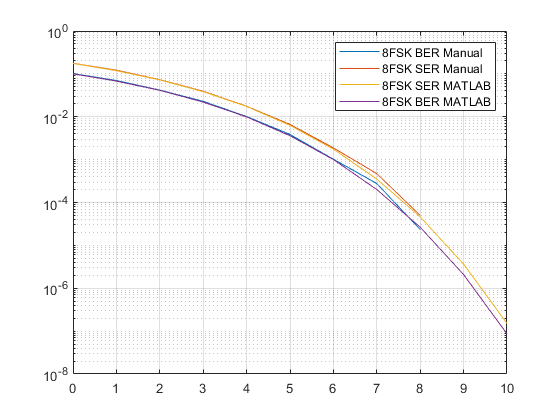

figure
[berFSK_matlab, serFSK_matlab] = berawgn(snr_db,modulation,M,'coherence');
semilogy(snr_db,berFSK)
hold on
semilogy(snr_db,serFSK)
hold on
semilogy(snr_db,serFSK_matlab)
hold on
semilogy(snr_db,berFSK_matlab)
legend('8FSK BER Manual','8FSK SER Manual', '8FSK SER MATLAB', '8FSK BER MATLAB')
grid on

figure

As we can see in BER plots we get same behaviour from both MATLAB Coherent FSK and our manual implementation.